# Spherical Pendulum Equations of Motion

Deriving the equations of motion of a spherical simple pendulum. The steps for solving a dynamics problem outlined here are based largely on those from Kasdin & Paley (2009). 

Copyright © 2021 Dmitry Savransky (ds264@cornell.edu)

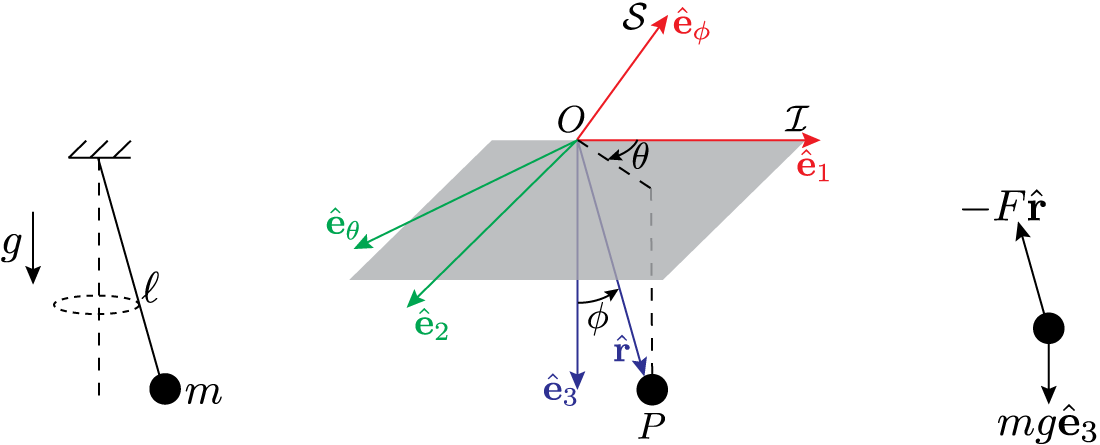

1.  **Model the system**: The spherical pendulum is modeled as a point mass *P* of mass *m, *attached to an ideal, frictionless, spherical bearing by a rigid, masless link of length $\ell$. The mass is free to travel anywhere in 3D space (so long as it remains an exact distance $\ell$ from the attachment point) and is acted on only by the force of gravity.

2. **Select the coordinates and reference frames**: We will use spherical angles $\left(\theta ,\phi \right)$ (azimuth and polar angles, respecitvely) to describe the position of the pendulum mass.  Since the mass is always at a fixed distance from its attachment point, the third spherical coordinate is constant such that $r\equiv \ell$for all time.  We will define our inertial frame $\mathcal I = (O, \mathbf{\hat{e}}_1,\mathbf{\hat{e}}_2,\mathbf{\hat{e}}_3)$, where $O$ is the attachment point, such that $\hat{\mathbf{e}}_3$ points in the direction of gravity.  The spherical coordinates naturally define a spherical frame $\mathcal S = (O, \mathbf{\hat{e}}_\phi, \mathbf{\hat{e}}_\theta, \mathbf{\hat{r}})$ where $\mathbf{\hat{r}}$ points from the attachment point to the pendulum mass (i.e., $\mathbf{\hat{r}}
$ is the unit direction of $\mathbf r_{P/O}$). Recall that the spherical frame is generated by executing a $\theta$ rotation about $\mathbf{\hat{e}}_3$ followed by a $\phi$rotation about $\mathbf{\hat{e}}_\theta$.  This means that the direction cosine matrix relating the two frames is given by ${}^\mathcal{S}C^\mathcal{I} = C_2(\phi)C_3(\theta)$.  We can also define the angular velocity of the spherical frame by inspection as: ${}^\mathcal{I}\mathbf{\omega}^\mathcal{S} = \dot\theta \mathbf{\hat{e}}_3 + \dot\phi\mathbf{\hat{e}}_\theta$.

3. **Draw the free-body diagram**: As there is only one mass, we only need one FBD.  The mass is acted upon only by gravity (in the positive $\mathbf{\hat{e}}_3$ direction) and by a constraint force due to the massless link, which acts in the negative $\mathbf{\hat{r}}
$ direction.  While we can immediately state the magnitude of the gravity force from our usual constant gravity model, the magnitude of the constraint force is unknown, and so we will just call it $F$.

Before proceeding, let's set up the variables and helper methods we'll need for the rest of the problem:

syms theta(t) phi(t)
syms l m g 'positive'
syms F th ph thd thdd phd phdd
rotMatE3 = @(ang) [cos(ang) sin(ang) 0;-sin(ang) cos(ang) 0;0 0 1];
rotMatE2 = @(ang) [cos(ang) 0 -sin(ang);0 1 0;sin(ang) 0 cos(ang)];
rotMatE1 = @(ang) [1 0 0;0 cos(ang) sin(ang);0 -sin(ang) cos(ang)];
rotMats = {rotMatE1,rotMatE2,rotMatE3};


$${}^\mathcal{S}C^\mathcal{I} = C_2(\phi)C_3(\theta)$$


sCi = rotMats{2}(phi)*rotMats{3}(theta)

$$sCi(t) = \left(\begin{array}{ccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) & 0\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


$${}^\mathcal{I}\mathbf{\omega}^\mathcal{S} = \dot\theta \mathbf{\hat{e}}_3 + \dot\phi\mathbf{\hat{e}}_\theta$$


As we will be working in spherical frame coordinates, it is convenient to write the angular velocity in components of this frame:


$$\left[{}^\mathcal{I}\mathbf{\omega}^\mathcal{S}\right]_\mathcal{S} = {}^\mathcal{S}C^\mathcal{I} \left[\matrix{ 0 \cr 0 \cr \dot\theta} \right]_\mathcal{I} + \left[\matrix{ 0 \cr \dot\phi \cr 0} \right]_\mathcal{S} $$


iWs = sCi*[0;0;diff(theta,t)] + [0;diff(phi,t);0] 

$$iWs(t) = \left(\begin{array}{c} -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\varphi \left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

4. **Calculate the Kinematics**: For a linear momentum balance approach (which is what we're doing here) these are the positions, velocities, and accelerations of masses.  For angular momentum balance, these are the angular momenta of all masses.  

In this case, the spherical frame makes it trivial to write the position vector of our point mass: $\left[\mathbf{r}_{P/O}\right]_\mathcal{S} = \left[ \matrix{ 0 \cr 0 \cr \ell}\right]_\mathcal{S} $

r_PO_S = [0;0;l]

$$r\_PO\_S = \left(\begin{array}{c} 0\\ 0\\ l \end{array}\right)$$

To find the** inertial** velocity and acceleration, we apply the transport equation twice.  In the first case, there is no body frame derivative, and so the inertial velocity is just ${}^\mathcal{I}\mathbf{\omega}^\mathcal{S}  \times \mathbf{r}_{P/O}$:

v_PO_S = cross(iWs,r_PO_S)

$$v\_PO\_S(t) = \left(\begin{array}{c} l\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ l\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

a_PO_S = simplify(diff(v_PO_S,t) + cross(iWs,v_PO_S))

$$a\_PO\_S(t) = \begin{array}{l} \left(\begin{array}{c} l\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)-\frac{l\,\sin\left(2\,\varphi \left(t\right)\right)\,\sigma_{1}}{2}\\ l\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,l\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -l\,{\sin\left(\varphi \left(t\right)\right)}^{2}\,\sigma_{1}-l\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

5. **Apply Newton's Second Law**: For each mass, we will apply either a linear momentum or angular momentum balance.  In this case, we'll apply a linear momentum balance (setting resultant forces equal to the mass times inertial acceleration for each mass), although we can equivalently solve the problem with an angular momentum balance. 

We can simply read off our resultant force from the free body diagram: $\mathbf{F}_P = -F\mathbf{\hat{r}} + m g \mathbf{e}_3$.  Once again, we wish to do everything in spherical frame components:

forces_S = [0;0;-F]+ sCi*[0;0;m*g]

$$forces\_S(t) = \left(\begin{array}{c} -g\,m\,\sin\left(\varphi \left(t\right)\right)\\ 0\\ g\,m\,\cos\left(\varphi \left(t\right)\right)-F \end{array}\right)$$

secondlaw = forces_S - m*a_PO_S %note that this matrix equals zero

$$secondlaw(t) = \begin{array}{l} \left(\begin{array}{c} -m\,\left(l\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)-\frac{l\,\sin\left(2\,\varphi \left(t\right)\right)\,\sigma_{1}}{2}\right)-g\,m\,\sin\left(\varphi \left(t\right)\right)\\ -m\,\left(l\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,l\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\\ m\,\left(l\,{\sin\left(\varphi \left(t\right)\right)}^{2}\,\sigma_{1}+l\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}\right)-F+g\,m\,\cos\left(\varphi \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

One finicky, MATLAB-specific thing:  at this point, the secondlaw variable is a symbolic function, but we want to later treat it as a symbolic variable, so we will redefine it as itself, but explicitly a function of the time variable:

secondlaw = secondlaw(t); 

6. **Find the scalar equations of motion**: using the second law vector equations, and any constraint equations, find a second-order differential equation for each coordinate (and an expression for any undetermined constraint forces, if desired.  In this case, we have three equations (the three components of the second law vector system) and three unknowns ($\ddot\theta, \ddot\phi, F$), and so we do not need any additional equations to solve the system. 

For legibility, and to allow MATLAB to solve this for us, we are going to substitute for the desired differential unknowns:

sys = subs(secondlaw,[diff(theta,t,2),diff(phi,t,2)],[thdd,phdd])

$$sys = \begin{array}{l} \left(\begin{array}{c} -m\,\left(l\,\mathrm{phdd}-\frac{l\,\sin\left(2\,\varphi \left(t\right)\right)\,\sigma_{1}}{2}\right)-g\,m\,\sin\left(\varphi \left(t\right)\right)\\ -m\,\left(2\,l\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\mathrm{thdd}\,\sin\left(\varphi \left(t\right)\right)\right)\\ m\,\left(l\,{\sin\left(\varphi \left(t\right)\right)}^{2}\,\sigma_{1}+l\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}\right)-F+g\,m\,\cos\left(\varphi \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

eom = solve(sys,[thdd, phdd, F])

eom = struct with fields:
    thdd: [1×1 sym]
    phdd: [1×1 sym]
       F: [1×1 sym]


eom.thdd, eom.phdd, eom.F

$$ans = -\frac{2\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{\sin\left(\varphi \left(t\right)\right)}$$

$$ans = -\frac{2\,g\,\sin\left(\varphi \left(t\right)\right)-l\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2\,l}$$

$$ans = l\,m\,{\sin\left(\varphi \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l\,m\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+g\,m\,\cos\left(\varphi \left(t\right)\right)$$

Our equations of motion are (remember that $\sin(2x) = 2\sin x\cos x$):


$$\ddot\theta = -2\frac{\dot\phi\dot\theta}{\tan\phi}$$



$$\ddot\phi = \left(-\frac{g}{l} + \dot\theta^2\cos\phi\right)\sin\phi$$


7.** Integrate the equations of motion**: If possible (usually not) analytically, otherwise numerically. In this case, we'll do it numerically with a MATLAB built-in integrator.  Remember: all of these want to solve a first order differential system of the form $\dot z = f(t,z)$, but we have second-order differential equations.  To solve this, we create a state variable composed of our coordinates and their time derivatives:


$$z = \left[\matrix{ \phi \cr \dot \phi \cr \theta \cr \dot\theta}\right]$$


g = 9.81; %m/s
l = 1; %m
%this is an anonymous function.  we can also define the 
%equations of motion as a spearate function or subfunction
dz1 = @(t,z) [z(2);
            z(4)^2*sin(z(1))*cos(z(1)) - g/l*sin(z(1));
            z(4);
            -2*z(4)*z(2)/tan(z(1))];

And now we can integrate:

% we need initial conditions (must match state order set in integrator
% function)
z0 = [30*pi/180,0,0,1];   

%we need an integration time span.  Minimally, we can specify a starting
%and ending point (i.e. tspan = [0,30];) but that allows the integrator to
%choose which time steps to output at, and they will not be equally spaced.
%If we want equally spaced outputs, we need to specify them. This will
%still allow the integrator to take whatever steps it wants, but the ouptut
%will be exactly at the times specified: 
tspan = linspace(0,30,1000);

%these two should produce exactly the same results:
[ts,zs] = ode45(dz1,tspan,z0);

Let's take a look at the results:

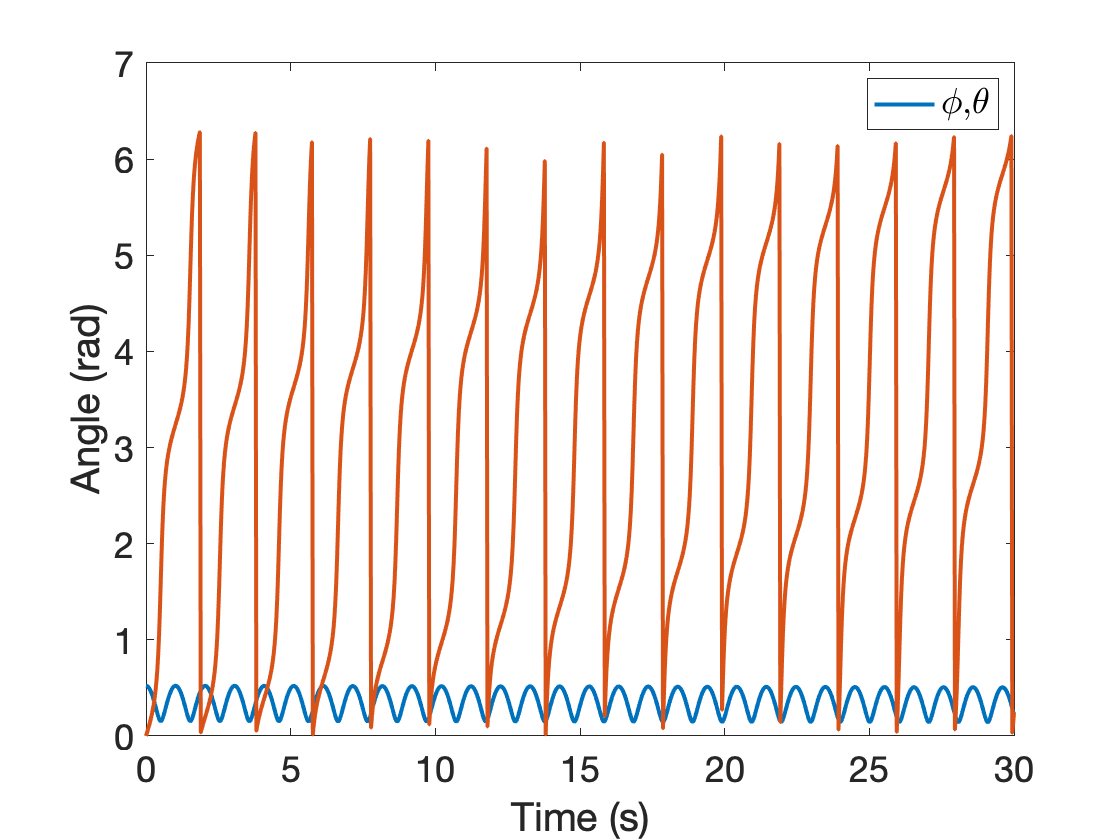

figure()
plot(ts,zs(:,1),ts,mod(zs(:,3),2*pi),'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Time (s)')
ylabel('Angle (rad)')
legend({'$\phi$,$\theta$'},'Interpreter','latex','FontSize',18)

We can also use animate the result (using a separate function):

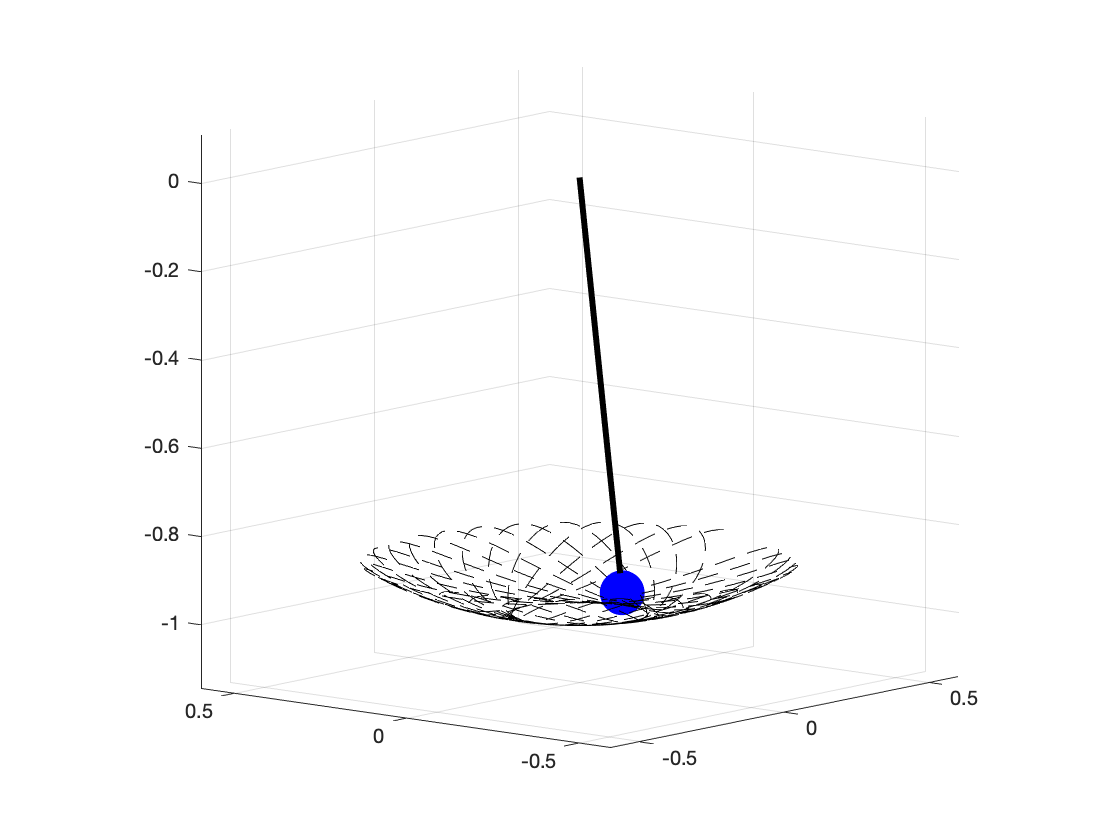

addpath('../Numerical Integration')
sphericalPendulumAnim(l,z0,true);